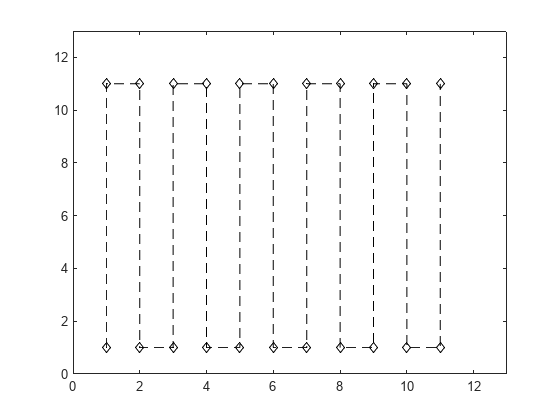

clear all;

path = ([1    1;
        1    11;
        2    11;
        2    1;
        3   1;
        3   11
        4   11
        4   1
        5   1
        5   11
        6   11
        6   1
        7 1
        7 11
        8 11
        8 1
        9 1
        9 11
        10 11
        10 1
        11 1
        11 11]);


robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 13])
ylim([0 13])

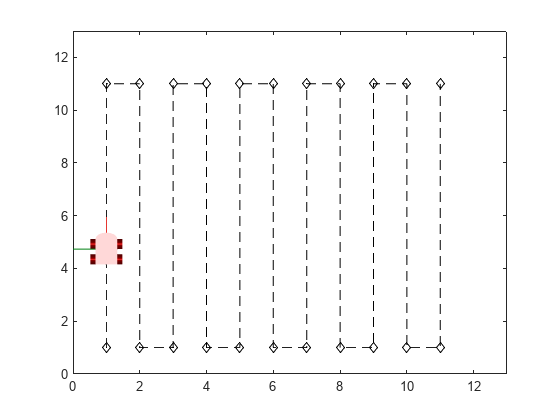


controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.6;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);
% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;


while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 13])
    ylim([0 13])
    
    waitfor(vizRate);
end

load exampleMaps

map = binaryOccupancyMap(simpleMap);
figure
show(map)
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);
prm.NumNodes = 200;
prm.ConnectionDistance = 10;


startLocation = [24 9];
endLocation = [4.0 5.0];
path = findpath(prm, startLocation, endLocation)

path =            24            9
       23.992       8.3404
       20.905       9.4868
        17.56       11.991
       16.583       13.768
       9.0959       15.286
       6.9691       11.899
       3.4828       6.2357
            4            5



show(prm);

load exampleMaps

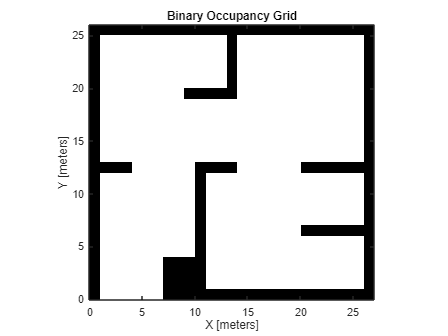

map = binaryOccupancyMap(simpleMap);
figure
show(map)


mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);
prm.NumNodes = 100;
prm.ConnectionDistance = 10;

startLocation = [4.0 2.0];
endLocation = [24.0 3.0];
path = findpath(prm, startLocation, endLocation)

path =             4            2
       3.6766       1.7417
       4.5471       6.7191
       7.5961       13.657
       12.283       15.346
       16.149       14.813
       17.848       7.4699
       18.903       3.4206
       22.041       2.8385
           24            3


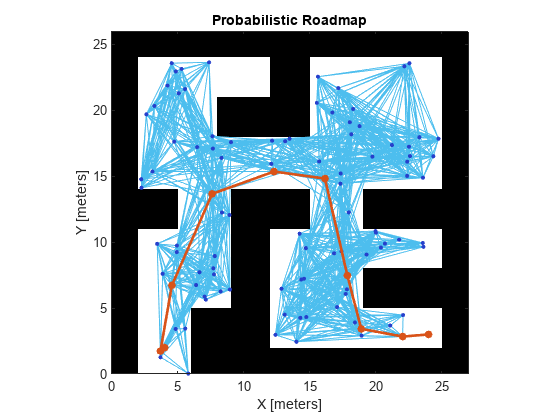


show(prm);

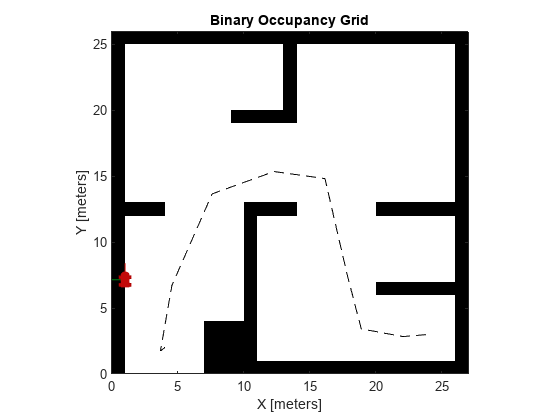


 % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    robotCurrentPose = [robotInitialLocation initialOrientation]';

goalRadius = 0.1;
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);
reset(vizRate);

% Initialize the figure
figure

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    show(map);
    hold all

    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, 'MeshFilePath', 'groundvehicle.stl', 'Parent', gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 27])
    ylim([0 26])
    
    waitfor(vizRate);
end

clear all;

path = ([1.00    1.00;
        1    11;
        2    11;
        2    1;
        3   1;
        3   11
        4   11
        4   1
        5   1
        5   11
        6   11
        6   1
        7 1
        7 11
        8 11
        8 1
        9 1
        9 1
        10 11
        10 1
        11 1
        11 11])

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");
robotInitialLocation = path(1,:);
robotGoal = path(end,:);
initialOrientation = 0;
robotCurrentPose = [robotInitialLocation initialOrientation]';


controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.6;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);
% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);


load exampleMaps
map = binaryOccupancyMap(simpleMap);
figure
show(map)

mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);

startLocation = [4.0 2.0];
endLocation = [24.0 3.0];




release(controller);
controller.Waypoints = path;

reset(vizRate);

frameSize = robot.TrackWidth/0.8;

% Initialize the figure
figure

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    show(map);
    hold all

    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, 'MeshFilePath', 'groundvehicle.stl', 'Parent', gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 27])
    ylim([0 26])
    
    waitfor(vizRate);
end